clear; clc; close all;

nfft = 128;
BW = 1000000;
M = 256;
ofdm_symbols = 10;
snr = 35;
%multipath = [1 0.1 0.3 0.3];
%multipath = [0 0 0 0 0 0 0 0 1 0.5 0.1 0 0];
multipath = [0.5 0.5 0.0];
multipath = 1;

cp_len = nfft/4;
rep = 4;
pilot_index = [4:rep:nfft-4];
pilot_carriers = length(pilot_index);
zp_index = [1:3,nfft-3:nfft];
zp_carriers = length(zp_index);
scs = BW/nfft;
cfo = scs/3;
cfo = 0;
cpo = pi/8;
cpo = 0

cpo = 0

Fs = BW;
Ts = 1/Fs;
t2 = 0:Ts:((nfft+cp_len)*ofdm_symbols-1)*Ts;
t = 0:Ts:(nfft+cp_len-1)*Ts;

**Transmit:**

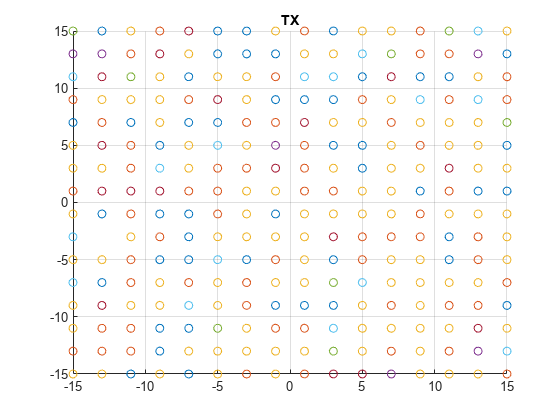

rng default
pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:M-1);
P = qammod(pilot_data,M);
%pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:4-1);
%P = qammod(pilot_data,4);
% P = [];
% for i = 1:ofdm_symbols
%     P(:,i) = zadoffChuSeq(1,pilot_carriers+1);
% end
% P(end,:) = [];
%pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:2-1);
%P = pskmod(pilot_data,2);
rng default
tx_data = randsrc(nfft,ofdm_symbols,0:M-1);
X = qammod(tx_data,M);
tx_data([pilot_index,zp_index],:) = [];
X(pilot_index,:) = P;

figure(),scatter(real(X),imag(X)),title('TX'),grid on

X(zp_index,:) = 0+0j;

x_pre_cp = ifft(X,nfft);
cp = x_pre_cp(nfft-cp_len+1:end,:);
x = vertcat(cp,x_pre_cp);

x = reshape(x,[(nfft+cp_len)*ofdm_symbols 1]);

**Channel:**

x_channel = awgn(x,snr,'measured');
%%%%%%%%%%%%% Demod with only SNR
x_rx_snr = reshape(x_channel,[nfft+cp_len ofdm_symbols]);
x_rx_snr = x_rx_snr(cp_len+1:end,:);
X_RX_snr = fft(x_rx_snr,nfft);
X_RX_pilot = X_RX_snr(pilot_index,:);
%X_RX_snr = X_RX_snr(pilot_index,:);
%x_channel = exp(-1i*cpo)*x_channel;

x_channel = exp(1i*cpo) * filter(multipath,1,x_channel) .* exp(1i*2*pi*cfo.*t2)';


**Demodulate:**

x_channel = reshape(x_channel,[nfft+cp_len ofdm_symbols]);

cp_rm = x_channel;
ofdm_signal_par = x_channel;
cp_rm(1:cp_len,:) = [];
ofdm_cfo_signal_par_eq = [];
cfo_est = 0;
for i = 1:ofdm_symbols
    cp_cfo_begin = ofdm_signal_par(1:cp_len,i);
    cp_cfo_end = (ofdm_signal_par(nfft+1:end,i));
    tmp = cp_cfo_end.*conj(cp_cfo_begin);
    mult_val = complex(real(cp_cfo_end.*conj(cp_cfo_begin)),imag(cp_cfo_end.*conj(cp_cfo_begin)));
    sum_val = sum(mult_val);
    tan_val = atan2(imag(sum_val),real(sum_val));
    normalized_cfo_est = 1*tan_val;
    cfo_est = normalized_cfo_est * scs;
    ofdm_cfo_signal_par_eq(:,i) = cp_rm(:,i).*(cos(cfo_est*t(1:nfft))+1i*sin(cfo_est*t(1:nfft)))';
end

% x_rx = x_channel(cp_len+1:end,:);
% for i = 1:ofdm_symbols
%     x_rx(:,i) = x_rx(:,i)*exp(-1j*0.2*i);
% end
X_RX = fft(ofdm_cfo_signal_par_eq,nfft);
P_RX = X_RX(pilot_index,:);
%X_RX(pilot_index,:) = [];
H = conj(P_RX) ./ conj(P);
H_ZF = H;

% Normal ZF with interpolation of channel estimates between pilot locations
H_ZF_interp = interp1(pilot_index,H_ZF,1:nfft,'nearest');
H_ZF_interp(isnan(H_ZF_interp))=0;
Z_EQ = X_RX .* conj(H_ZF_interp);

%%%%% edit
H_P2 = mean(H);
Z_EQ1 = X_RX ./ conj(H_P2);
P_RX = Z_EQ1(pilot_index,:);
H = conj(P_RX) ./ conj(P);
H_ZF = H;
%%%%%

% Average channel estimates over a window
freq_avg = 1;
time_avg = 5;
H_est_avg = X_RX;
H_ZF_save = zeros(pilot_carriers,ofdm_symbols);
Z_EQ2 = X_RX;
for i = 1:ofdm_symbols
    for k = 1:pilot_carriers
        index = ((rep)*(k-1)+1:(rep)*k) + zp_index(ceil(end/2)-1);
        ind_lo = k-floor(freq_avg/2);
        ind_hi = k+floor(freq_avg/2);
        if ind_lo < 1
            ind_lo = 1;
        end
        if ind_hi > pilot_carriers
            ind_hi = pilot_carriers;
        end
        i_lo = i-floor(time_avg/2);
        i_hi = i+floor(time_avg/2);
        if i_lo < 1
            i_lo = 1;
        end
        if i_hi > ofdm_symbols
            i_hi = ofdm_symbols;
        end
        H_tmp = mean(mean(H_ZF(ind_lo:ind_hi,i_lo:i_hi)));
        H_ZF_save(k,i) = conj(H_tmp);
        H_est_avg(index,i) = ones(1,length(index))*H_tmp;
        Z_EQ2(index,i) = X_RX(index,i) / conj(H_tmp);
    end
end

% Interpolate Averaged channel estimates
H_ZF2_interp = interp1(pilot_index,H_ZF_save,1:nfft,'spline');
%Z_EQ3 = X_RX .* H_ZF2_interp;
Z_EQ3 = Z_EQ1 ./ H_ZF2_interp;

% 2nd stage ZF phase only averaged accross 1 symbol, calculate new channel after 1st stage
P_RX2 = Z_EQ3(pilot_index,:);
H2 = conj(P_RX2) ./ conj(P);
H_P = mean(H2);
Z_EQ4 = Z_EQ3 ./ conj(H_P);

% AWGN only ideal channel compare to equalizer
X_RX_snr([pilot_index,zp_index],:) = [];
% AWGN + channel
X_RX([pilot_index,zp_index],:) = [];
% Normal ZF
Z_EQ([pilot_index,zp_index],:) = [];
% ZF Estimation window average
Z_EQ2([pilot_index,zp_index],:) = [];
% Interpolated ZF Estimation window average
Z_EQ3([pilot_index,zp_index],:) = [];
% 2nd Stage symbol averaged ZF equalization
Z_EQ4([pilot_index,zp_index],:) = [];

rx = qamdemod(X_RX_snr,M);
no_eq = qamdemod(X_RX,M);
zf_eq = qamdemod(Z_EQ,M);
zf_eq_avg = qamdemod(Z_EQ2,M);
zf_eq_avg_interp = qamdemod(Z_EQ3,M);
zf_eq_phase = qamdemod(Z_EQ4,M);

rx_ser = symerr(tx_data,rx)/numel(tx_data);
no_eq_ser = symerr(tx_data,no_eq)/numel(tx_data);
zf_eq_ser = symerr(tx_data,zf_eq)/numel(tx_data);
zf_eq_avg_ser = symerr(tx_data,zf_eq_avg)/numel(tx_data);
zf_eq_avg_interp_ser = symerr(tx_data,zf_eq_avg_interp)/numel(tx_data);
zf_eq_phase_ser = symerr(tx_data,zf_eq_phase)/numel(tx_data);

X_tx = X;
X([pilot_index,zp_index],:) = [];
evm = comm.EVM(AveragingDimensions=[1 2],MaximumEVMOutputPort=1);
[rx_evm,rx_pk] = evm(X,X_RX_snr);
[no_eq_evm,no_eq_pk] = evm(X,X_RX);
[zf_eq_evm,zf_eq_pk] = evm(X,Z_EQ);
[zf_eq_avg_evm,zf_eq_avg_pk] = evm(X,Z_EQ2);
[zf_eq_avg_interp_evm,zf_eq_avg_interp_pk] = evm(X,Z_EQ3);
[zf_eq_phase_evm,zf_eq_phase_pk] = evm(X,Z_EQ4);


Equalization = ["AWGN";"No Equalization";"ZF";"ZF Windowed Average";"Interpolated ZF Windowed Average";"2nd Stage Symbol Averaged ZF"];
SER = [rx_ser;no_eq_ser;zf_eq_ser;zf_eq_avg_ser;zf_eq_avg_interp_ser;zf_eq_phase_ser];
AverageEVM = [rx_evm;no_eq_evm;zf_eq_evm;zf_eq_avg_evm;zf_eq_avg_interp_evm;zf_eq_phase_evm];
PeakEvm = [rx_pk;no_eq_pk;zf_eq_pk;zf_eq_avg_pk;zf_eq_avg_interp_pk;zf_eq_phase_pk];

table(Equalization,SER,AverageEVM,PeakEvm)

ans = 6×4 table
               Equalization                  SER       AverageEVM    PeakEvm
    __________________________________    _________    __________    _______

    "AWGN"                                        0      1.7134      4.6683 
    "No Equalization"                             0      1.7164      4.6988 
    "ZF"                                  0.0077778      3.0125      15.832 
    "ZF Windowed Average"                         0      2.0786      5.6634 
    "Interpolated ZF Windowed Average"            0      2.0692      6.3852 
    "2nd Stage Symbol Averaged ZF"                0       2.069      6.3862 


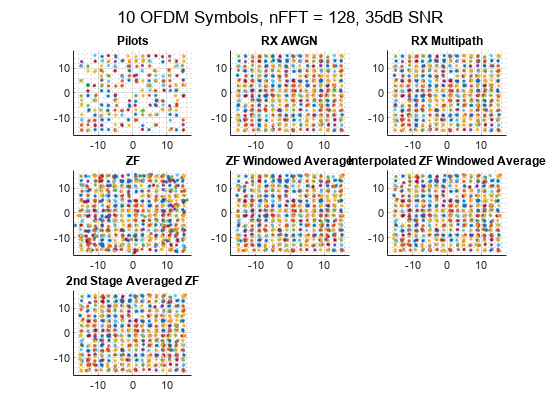


%y_lim = [-2 2]; x_lim = [-2 2];
lim = sqrt(M) + 1.5;
y_lim = [-lim lim]; x_lim = [-lim lim]; 
%y_lim = [-5 5]; x_lim = [-5 5]; % 16 QAM
%ylim = [-7 7]; x_lim = [-7 7]; % 32 QAM
%y_lim = [-9 9]; x_lim = [-9 9]; % 64 QAM
%y_lim = [-15 15]; x_lim = [-15 15]; % 128 QAM
%y_lim = [-19 19]; x_lim = [-19 19]; % 256 QAM
figure(),subplot(3,3,1),scatter(real(X_RX_pilot),imag(X_RX_pilot),'.','LineWidth',2),grid on,grid minor,title('Pilots'),xlim(x_lim),ylim(y_lim)
subplot(3,3,2),scatter(real(X_RX_snr),imag(X_RX_snr),'.','LineWidth',2),grid on,grid minor,title('RX AWGN'),xlim(x_lim),ylim(y_lim)
subplot(3,3,3),scatter(real(X_RX),imag(X_RX),'.','lineWidth',2),grid on,grid minor,title('RX Multipath'),xlim(x_lim),ylim(y_lim)
subplot(3,3,4),scatter(real(Z_EQ),imag(Z_EQ),'.','lineWidth',2),grid on,grid minor,title('ZF'),xlim(x_lim),ylim(y_lim)
subplot(3,3,5),scatter(real(Z_EQ2),imag(Z_EQ2),'.','lineWidth',2),grid on,grid minor,title('ZF Windowed Average'),xlim(x_lim),ylim(y_lim)
subplot(3,3,6),scatter(real(Z_EQ3),imag(Z_EQ3),'.','LineWidth',2),grid on,grid minor,title('Interpolated ZF Windowed Average'),xlim(x_lim),ylim(y_lim)
subplot(3,3,7),scatter(real(Z_EQ4),imag(Z_EQ4),'.','lineWidth',2),grid on,grid minor,title('2nd Stage Averaged ZF'),xlim(x_lim),ylim(y_lim)
sgtitle([num2str(ofdm_symbols),' OFDM Symbols, nFFT = ',num2str(nfft),', ',num2str(snr),'dB SNR'])

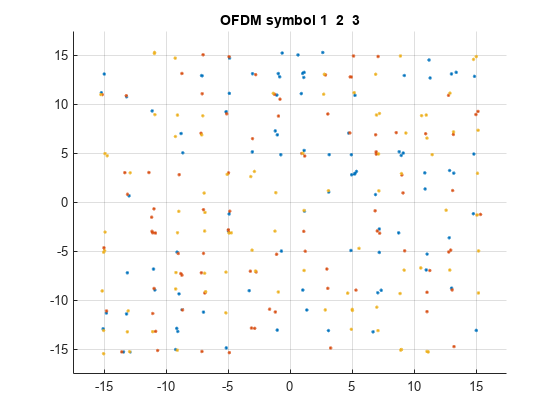

symb = 1:3;
figure(),scatter(real(Z_EQ4(:,symb)),imag(Z_EQ4(:,symb)),'.','LineWidth',2),grid on,xlim(x_lim),ylim(y_lim)
title(['OFDM symbol ',num2str(symb)])

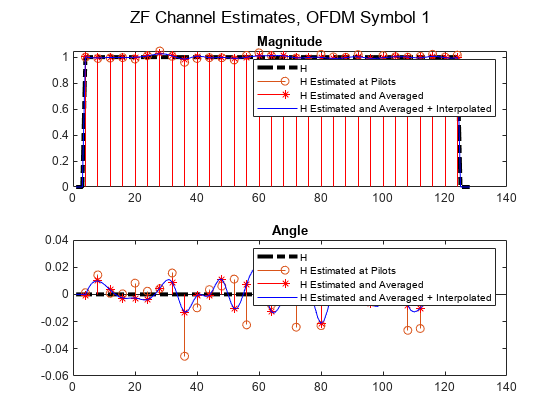

% Plot Channel estimation vs actual channel
symb = 1;
y1 = 1:nfft;
y1(zp_index) = [];
H_true = [1 zeros(1,(nfft+cp_len)-1)]';
H_true = H_true * ones(1,ofdm_symbols);
H_true = reshape(H_true,[(nfft+cp_len)*ofdm_symbols 1]);
%H_true = [1 zeros(1,((nfft+cp_len)*ofdm_symbols)-1)]';
H_true = filter(multipath,1,H_true);
H_true = exp(-1i*cpo)*H_true.*exp(-1i*2*pi*cfo.*t2)';
H_true = reshape(H_true,[nfft+cp_len ofdm_symbols]);
H_true = fft(H_true,nfft);
H_true = fftshift(H_true);
H_true(zp_index,:) = 0;
H_true_abs = abs(H_true);
%H_true_abs = (-1*(abs(H_true)-1))+1;
H_true_angle = angle(conj(H_true));
H_ZF2_interp(zp_index,:) = 0;

H_est_avg(zp_index,:) = [];
figure(),subplot(2,1,1),plot(1:nfft,H_true_abs(:,symb),'-.k','LineWidth',3),hold on,
stem(pilot_index,abs(H_ZF(:,symb)))
stem(pilot_index,abs(H_ZF_save(:,symb)),'*r')
plot(1:nfft,abs(H_ZF2_interp(:,symb)),'b')
title('Magnitude')
legend('H','H Estimated at Pilots','H Estimated and Averaged','H Estimated and Averaged + Interpolated')
subplot(2,1,2),plot(1:nfft,H_true_angle(:,symb),'-.k','LineWidth',3),hold on,
stem(pilot_index,angle(H_ZF(:,symb)))
stem(pilot_index,angle(conj(H_ZF_save(:,symb))),'*r')
plot(1:nfft,angle(conj(H_ZF2_interp(:,symb))),'b')
title('Angle')
legend('H','H Estimated at Pilots','H Estimated and Averaged','H Estimated and Averaged + Interpolated')
sgtitle(['ZF Channel Estimates, OFDM Symbol ',num2str(symb)])

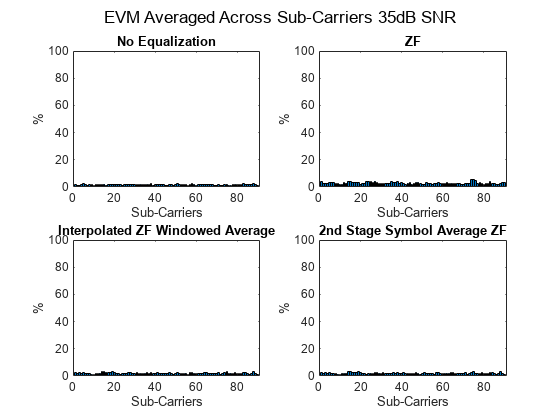

evm = comm.EVM(AveragingDimensions=2);
no_eq_evm = evm(X,X_RX);
zf_eq_evm = evm(X,Z_EQ) ;
zf_eq_2_evm = evm(X,Z_EQ4);
zf_eq_avg_interp_evm = evm(X,Z_EQ3);

y_lim = [0 100];
y = 1:nfft-zp_carriers-pilot_carriers;
figure(),subplot(2,2,1),bar(y,no_eq_evm),title('No Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,2),bar(y,zf_eq_evm),title('ZF'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,3),bar(y,zf_eq_avg_interp_evm),title('Interpolated ZF Windowed Average'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,4),bar(y,zf_eq_2_evm),title('2nd Stage Symbol Average ZF'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
sgtitle(['EVM Averaged Across Sub-Carriers ',num2str(snr),'dB SNR'])

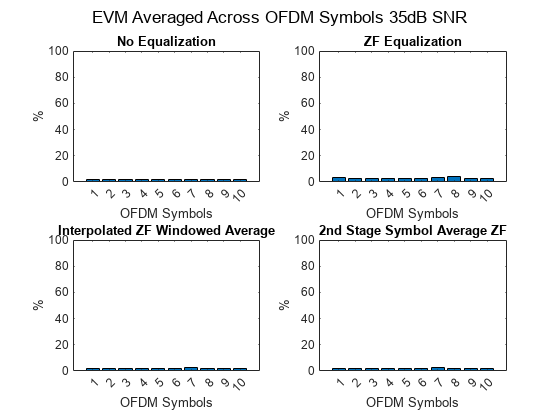

% Plot EVM vs OFDM Symbols
evm = comm.EVM(AveragingDimensions=1);
no_eq_evm = evm(X,X_RX);
zf_eq_evm = evm(X,Z_EQ) ;
zf_eq_2_evm = evm(X,Z_EQ4);
zf_eq_avg_interp_evm = evm(X,Z_EQ3);

y_lim = [0 100];
figure(),subplot(2,2,1),bar(1:ofdm_symbols,no_eq_evm),title('No Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
subplot(2,2,2),bar(1:ofdm_symbols,zf_eq_evm),title('ZF Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
subplot(2,2,3),bar(1:ofdm_symbols,zf_eq_avg_interp_evm),title('Interpolated ZF Windowed Average'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
subplot(2,2,4),bar(1:ofdm_symbols,zf_eq_2_evm),title('2nd Stage Symbol Average ZF'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
sgtitle(['EVM Averaged Across OFDM Symbols ',num2str(snr),'dB SNR'])

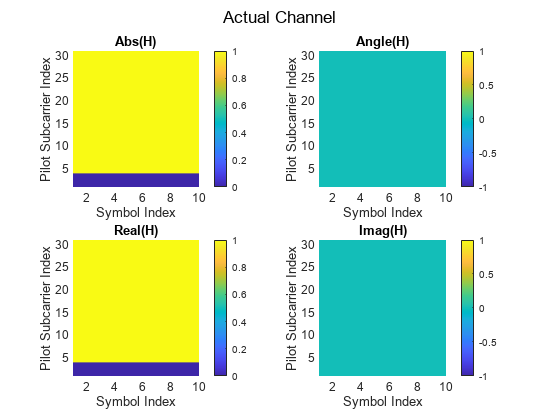

figure(),subplot(2,2,1),s = surf(abs(H_true)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Abs(H)')
subplot(2,2,2),s = surf(angle(H_true)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Angle(H)')
subplot(2,2,3),s = surf(real(H_true)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Real(H)')
subplot(2,2,4),s = surf(imag(H_true)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Imag(H)')
sgtitle('Actual Channel')

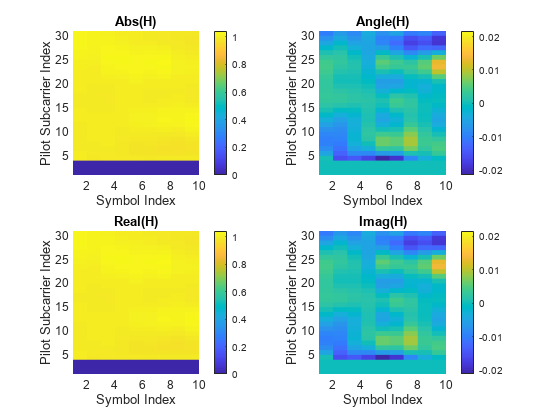


H_true = H_ZF2_interp;
figure(),subplot(2,2,1),s = surf(abs(H_true)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Abs(H)')
subplot(2,2,2),s = surf(angle(H_true)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Angle(H)')
subplot(2,2,3),s = surf(real(H_true)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Real(H)')
subplot(2,2,4),s = surf(imag(H_true)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Imag(H)')